Pierwsza metoda Lapunova

1.1 Układ mechaniczny

b = 0.8;
c = 0.7;
d1 = 1;
d2 = -1;
x0 = [1 1]

x0 =      1     1


J1 = [0 1; -c -b];
J5 = [0 1; 2*c -b];
eig(J1)

ans =   -0.4000 + 0.7348i
  -0.4000 - 0.7348i


eig(J5)

ans =     0.8490
   -1.6490


J1 = [-120 -60; 0 30 ]

J1 =   -120   -60
     0    30


eig(J1)

ans =   -120
    30


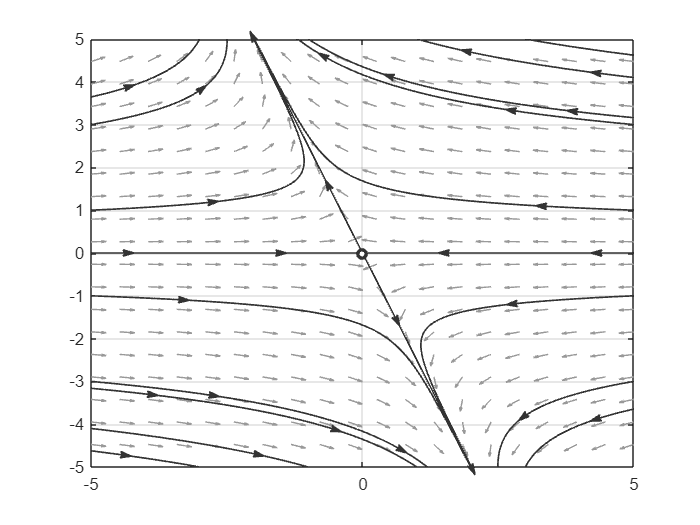

plotpp(@(t, x) J1*[x(1); x(2)])

%krok 3
close all;
x0 = [0.1 0.1]

x0 =     0.1000    0.1000


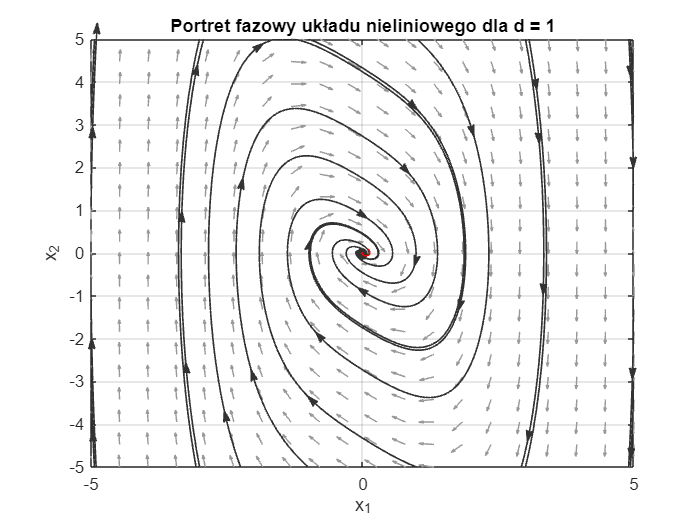


%%%%%
[t,x] = ode45(@(t,x) system31(t,x,b,c,d1), [0 100], x0);
plotpp(@(t,x)[x(2);-c*x(1) - d1*x(1)^3 - b*x(2)])
hold on
plot(x(:, 1), x(:, 2), 'r-')
hold off
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego dla d = 1")
saveas(gcf,'1.png')

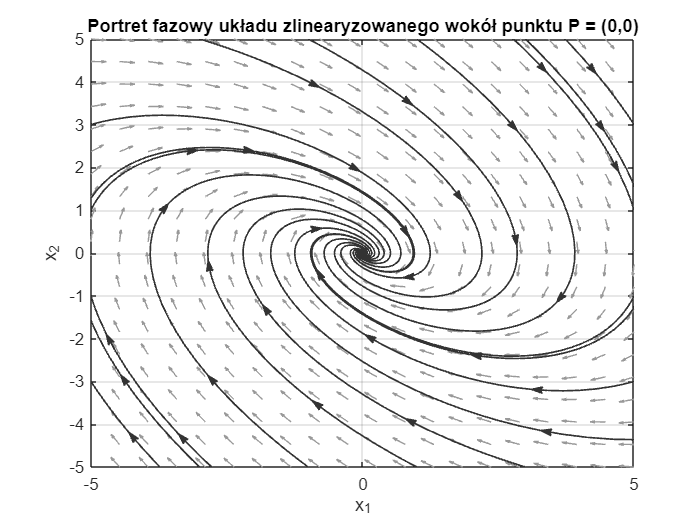

%krok 5
close all;
plotpp(@(t, x) J1*[x(1); x(2)])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego wokół punktu P = (0,0)")
saveas(gcf,'2.png')

close all;
x0 = [0 0.5]

x0 =          0    0.5000


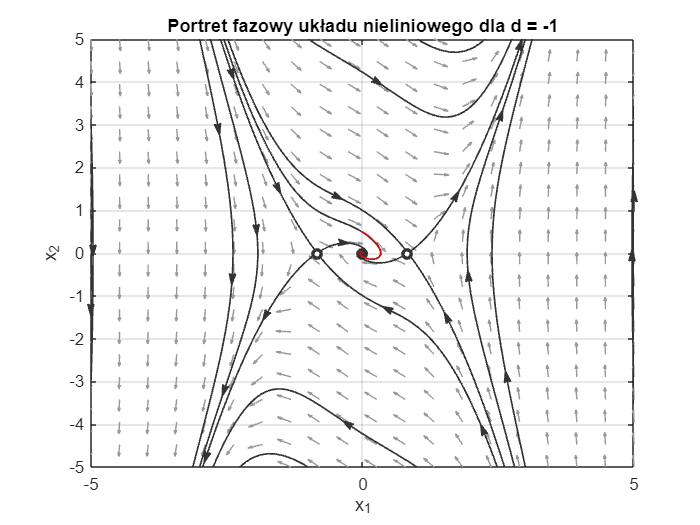

[t,x] = ode45(@(t,x) system31(t,x,b,c,d2), [0 100], x0);
plotpp(@(t,x)[x(2);-c*x(1) - d2*x(1)^3 - b*x(2)])
xlabel("x_1")
ylabel("x_2")
hold on
plot(x(:, 1), x(:, 2), 'r-')
hold off
title("Portret fazowy układu nieliniowego dla d = -1")
saveas(gcf,'3.png')

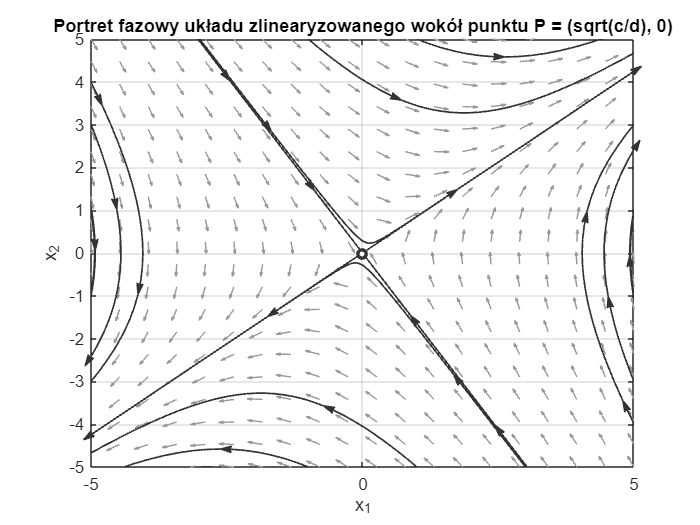

plotpp(@(t, x) J5*[x(1); x(2)])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego wokół punktu P = (sqrt(c/d), 0)")
saveas(gcf,'4.png')

%x1 - położenie
%x2 - prędkość

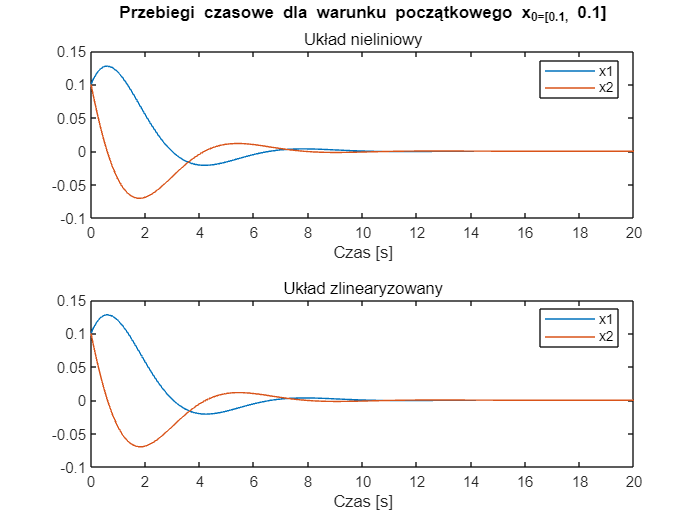

%krok 6
figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b=1;c=1;d=2;
x0=[0.1, 0.1];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
b=1;c=1;d=2;
x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[0, 1; -3*d*x(1)^2-c, -b];
T=6;
x0=[0.1, 0.1];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'5.png')

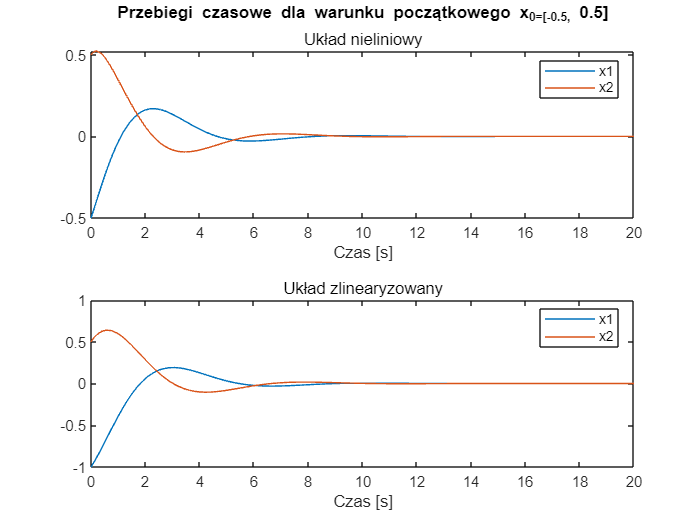

figure 
close all;
clear all;
subplot(2,1,1)
sim_time = 20;
b=1;c=1;d=2;
x0=[-0.5, 0.5];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
b=1;c=1;d=2;
x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[0, 1; -3*d*x(1)^2-c, -b];
T=6;
x0=[-1, 0.5];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'6.png')

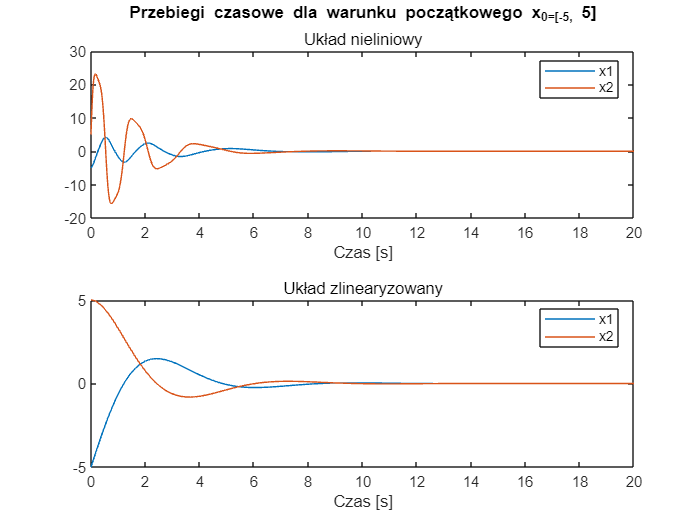

figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b=1;c=1;d=2;
x0=[-5, 5];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
b=1;c=1;d=2;
x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[0, 1; -3*d*x(1)^2-c, -b];
T=6;
x0=[-5, 5];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'7.png')

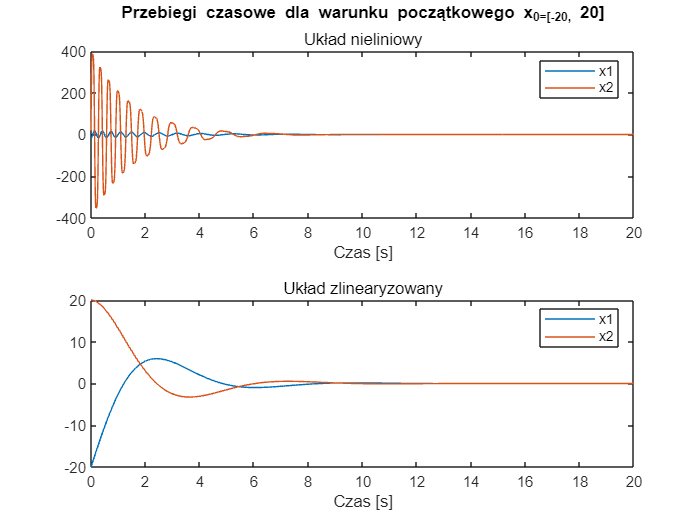

figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b=1;c=1;d=2;
x0=[-20, 20];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
b=1;c=1;d=2;
x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[0, 1; -3*d*x(1)^2-c, -b];
T=6;
x0=[-20,20];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'8.png')

1.2 Wahadło

clear all;
c = 2.5;
m = 5;
l = 5;
g = 9.81;
J3 = [0 1; (-g/l) (-c/(l*m))];
eig(J3)

ans =   -0.0500 + 1.3998i
  -0.0500 - 1.3998i


J4 = [0 1; (g/l) (-c/(l*m))];
eig(J4)

ans =     1.3516
   -1.4516


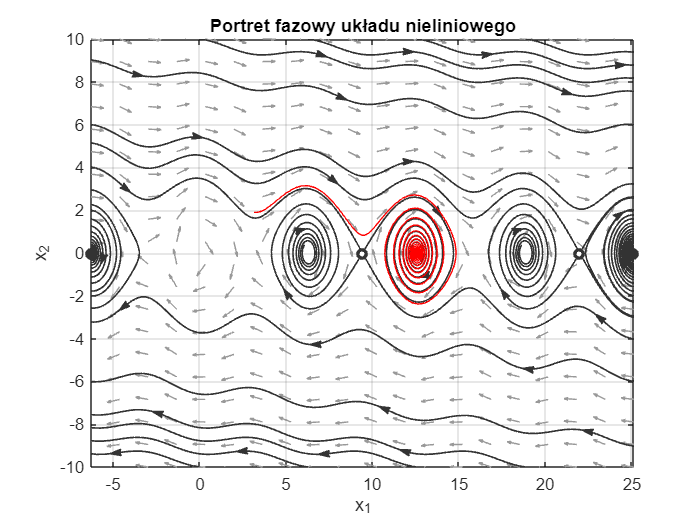

%krok 9.1
close all;
c = 2.5;
m = 5;
l = 5;
g = 9.81;

x0 = [pi 1.9]; %jeden obrót a dla 10 2 obroty
[t,x] = ode45(@(t,x) system32(t,x,c,l,m, g), [0 100], x0);
figure
plotpp(@(t,x)[x(2);-(g/l) *sin(x(1)) - (c/(l*m))*x(2)], 'xlim', [-2*pi, 8*pi], 'ylim', [-10, 10])
hold on
plot(x(:, 1), x(:, 2), 'r-')
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
hold off
saveas(gcf,'10.png')

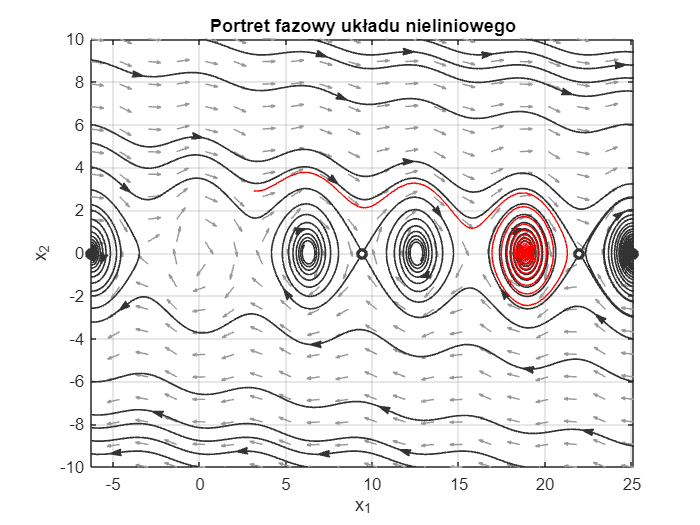

%krok 9.2
close all;
c = 2.5;
m = 5;
l = 5;
g = 9.81;
x0 = [pi 2.9]; %jeden obrót a dla 10 2 obroty
[t,x] = ode45(@(t,x) system32(t,x,c,l,m, g), [0 100], x0);
figure
plotpp(@(t,x)[x(2);-(g/l) *sin(x(1)) - (c/(l*m))*x(2)], 'xlim', [-2*pi, 8*pi], 'ylim', [-10, 10])
hold on
plot(x(:, 1), x(:, 2), 'r-')
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
hold off
saveas(gcf,'11.png')

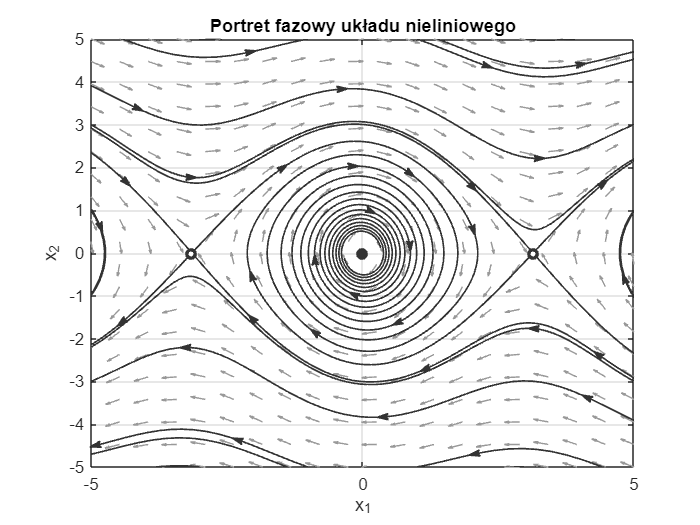

c = 2.5;
m = 5;
l = 5;
g = 9.81;
x0 = [2*pi 0]; 
[t,x] = ode45(@(t,x) system32(t,x,c,l,m, g), [0 100], x0);
figure
plotpp(@(t,x)[x(2);-(g/l) *sin(x(1)) - (c/(l*m))*x(2)])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
saveas(gcf,'12.png')

dla k = 2pi

%krok 10
J3 = [0 1; (-g/l)*cos(x(1)) (-c/(l*m))];
eig(J3)

ans =     1.3516
   -1.4516


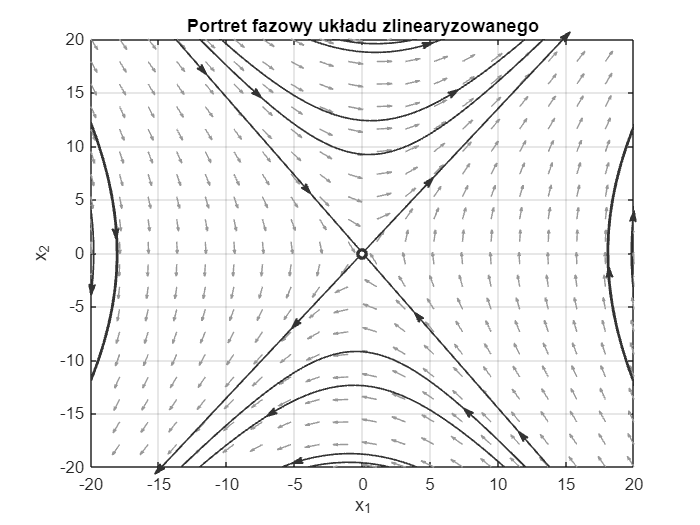

plotpp(@(t, x) J3*[x(1); x(2)], 'xlim', [-20, 20], 'ylim', [-20, 20])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego")
saveas(gcf,'13.png')

dla k = 2*pi + 1

%krok 10
J4 = [0 1; (g/l)*cos(x(1)) (-c/(l*m))];
eig(J4)

ans =   -0.0500 + 1.3998i
  -0.0500 - 1.3998i


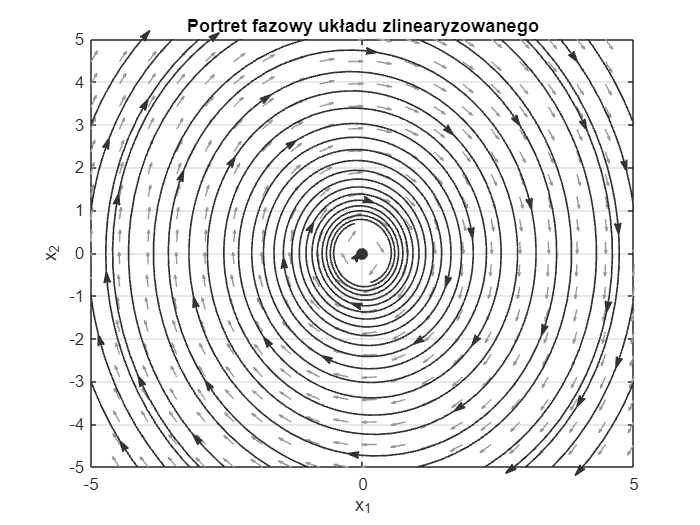

plotpp(@(t, x) J4*[x(1); x(2)])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego")
saveas(gcf,'14.png')

Układ Van der Pola

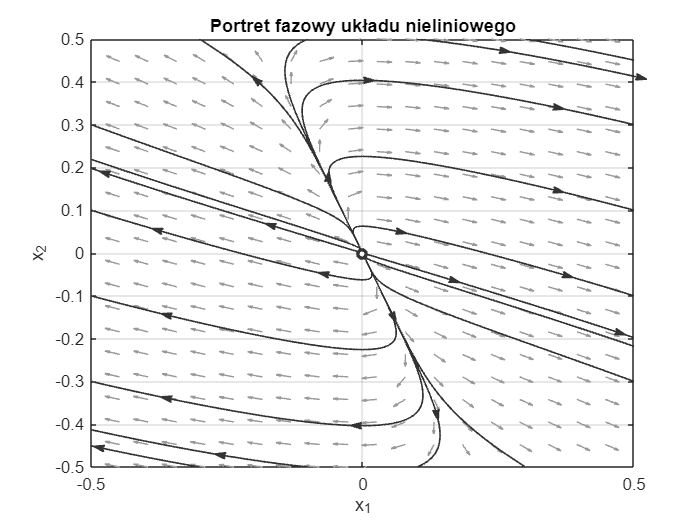

%krok 12 portret fazowy układu nieliniowego
close all;
a = -3;
x0 = [1 1];
[t,x] = ode45(@(t,x) system33(t,x,a), [0, 100], x0);
plotpp(@(t,x)[-x(1)^3 - a*x(1) + x(2); -x(1)], 'xlim', [-0.5, 0.5], 'ylim', [-0.5, 0.5])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
saveas(gcf,'15.png')

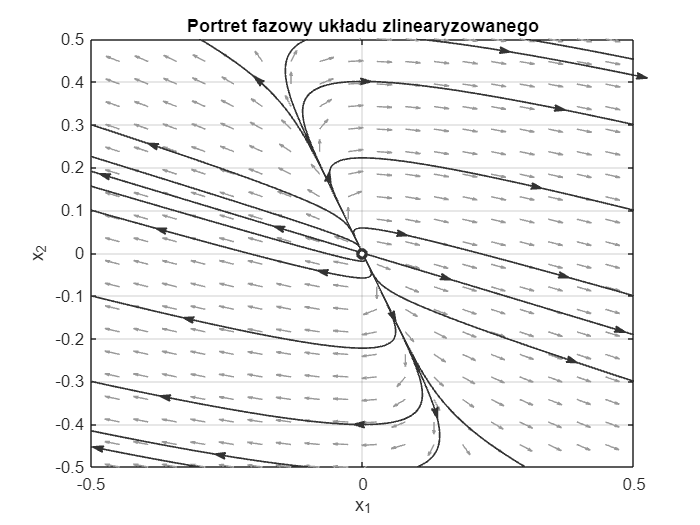


%krok12 portret fazowy układu zlinearyzowanego 
J = [-a 1; -1 0];
eig(J);
plotpp(@(t,x) J*[x(1);x(2)], 'xlim', [-0.5, 0.5], 'ylim', [-0.5, 0.5])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego")
saveas(gcf,'16.png')

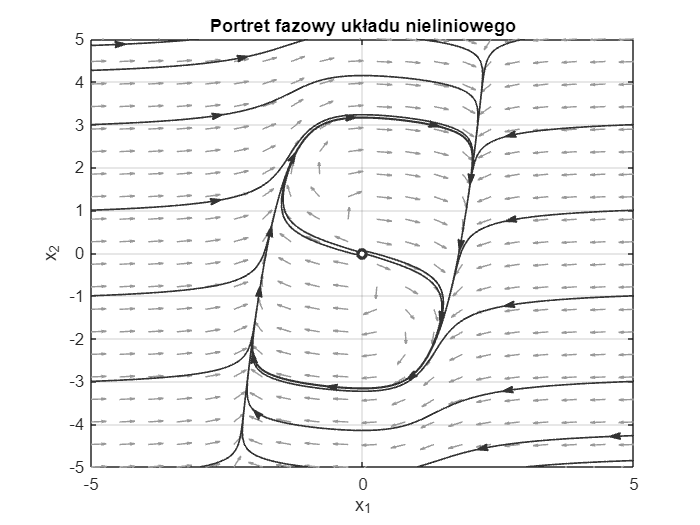

%krok 12 portret fazowy układu nieliniowego
close all;
a = -3;
x0 = [1 1];
[t,x] = ode45(@(t,x) system33(t,x,a), [0, 100], x0);
plotpp(@(t,x)[-x(1)^3 - a*x(1) + x(2); -x(1)])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
saveas(gcf,'17.png')


%krok12 portret fazowy układu zlinearyzowanego
J = [-a 1; -1 0];
eig(J)

ans =     2.6180
    0.3820


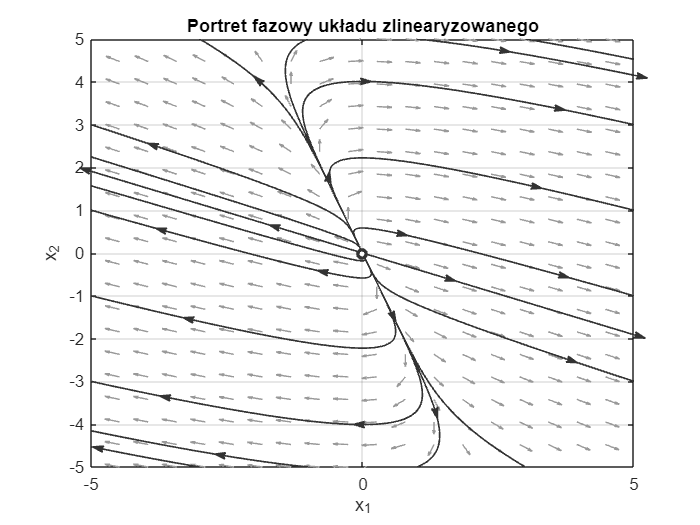

plotpp(@(t,x) J*[x(1);x(2)])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego")
saveas(gcf,'18.png')

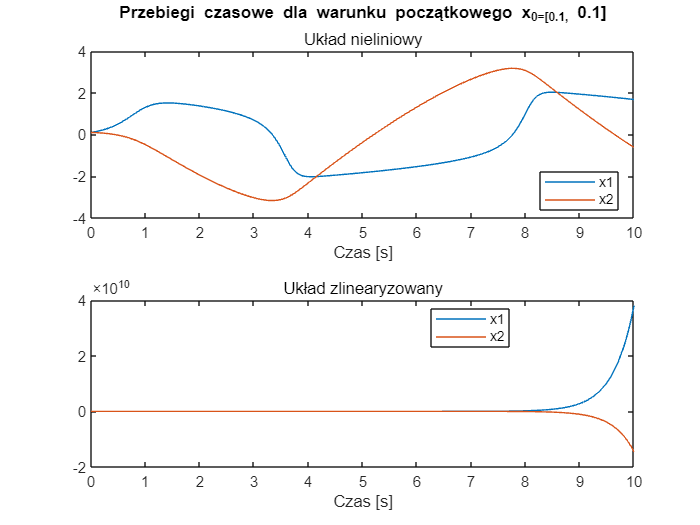

figure 
close all;
clear all;
sim_time = 10;
subplot(2,1,1)
a = -3;
x0=[0.1, 0.1];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
a = -3;
x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
T=6;
x0=[0.1, 0.1];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'19.png')

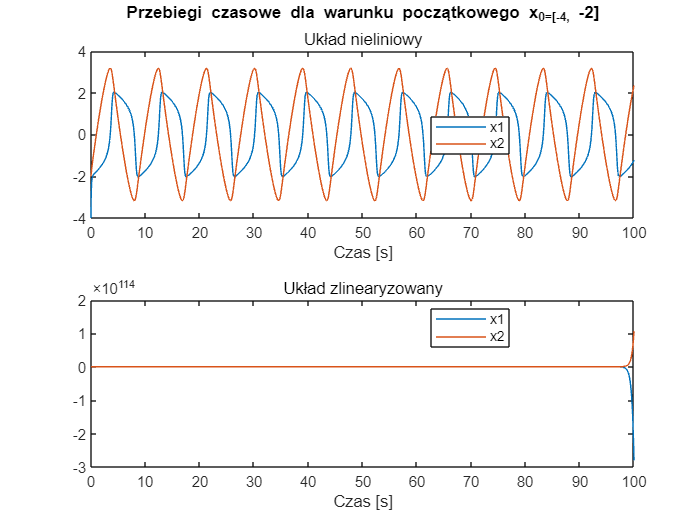

figure 
close all;
clear all;
sim_time = 100;
subplot(2,1,1)
a = -3;
x0=[-4, -2];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
a = -3;
x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
T=6;
x0=[-4, -2];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'20.png')

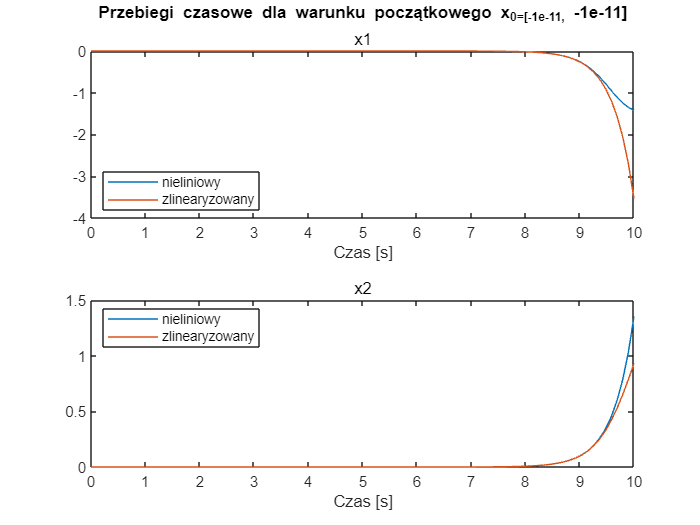

close all;
clear all;
sim_time = 10;
x0=[-1e-11, -1e-11];
a = -3;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = -3;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t1,xx1(:,2))
hold on 
plot(t, xx(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off
saveas(gcf,'21.png')

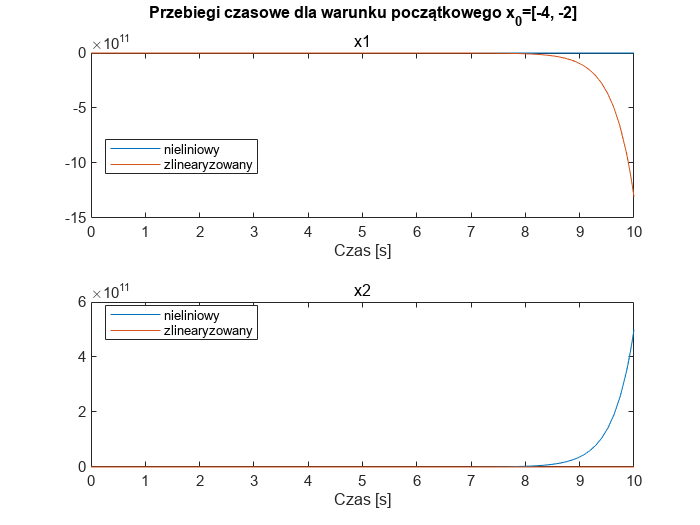

close all;
clear all;
sim_time = 10;
x0=[-4, -2];
a = -3;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = -3;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t1,xx1(:,2))
hold on 
plot(t, xx(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off

saveas(gcf,'22.png')

%Zadanie dodatkowe
% a = -3
close all;
a = -3;
x0 = [1 1];
[t,x] = ode45(@(t,x) system33(t,x,a), [0, 100], x0);
J = [-a 1; -1 0];
eig(J)

ans =     2.6180
    0.3820


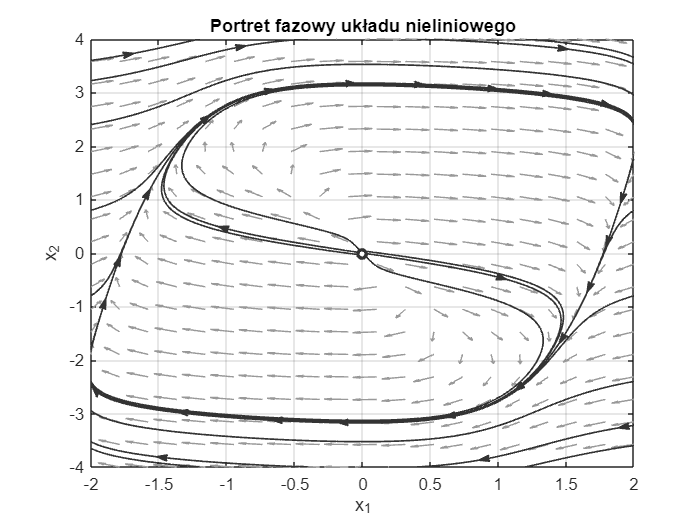

plotpp(@(t,x)[-x(1)^3 - a*x(1) + x(2); -x(1)], 'xlim', [-2, 2], 'ylim', [-4, 4])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
saveas(gcf,'23.png')

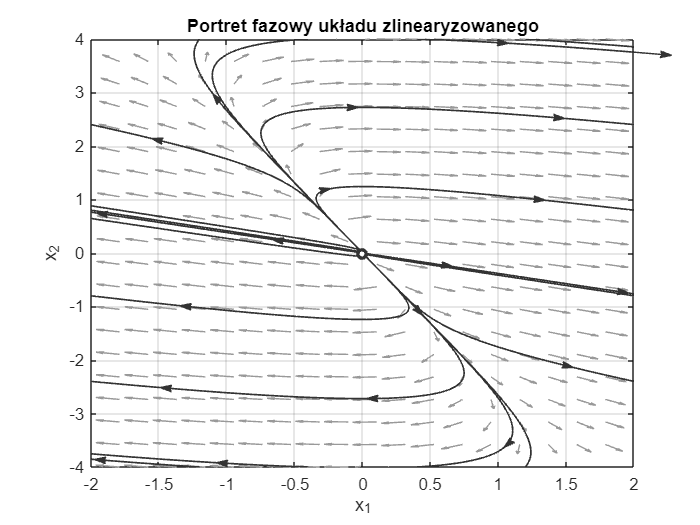


plotpp(@(t,x) J*[x(1);x(2)], 'xlim', [-2, 2], 'ylim', [-4, 4])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego")
saveas(gcf,'24.png')

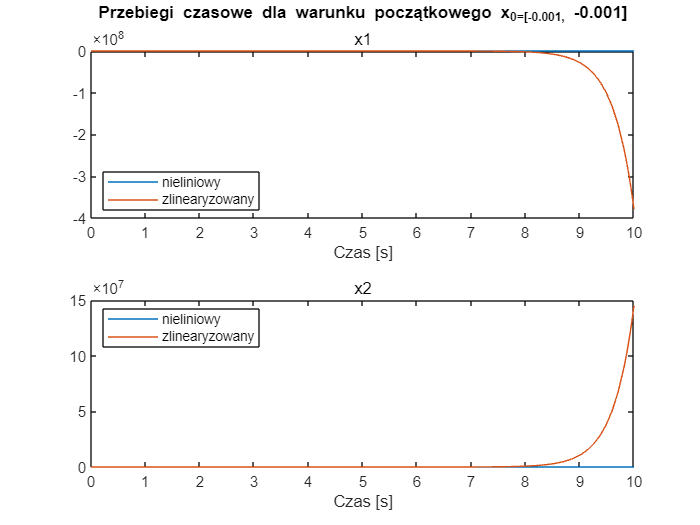

%zadanie dodatkowe przebiegi czasowe
close all;
clear all;
sim_time = 10;
x0=[-0.001 -0.001];
a = -3;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = -3;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t,xx(:,2))
hold on 
plot(t1, xx1(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off
saveas(gcf,'31.png')

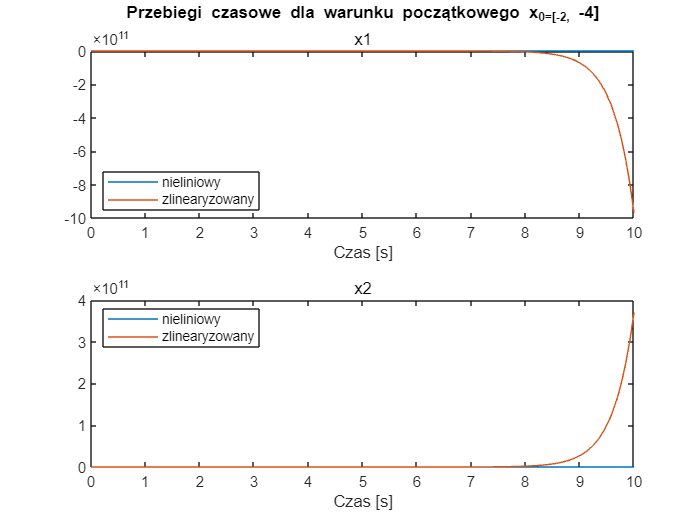


%zadanie dodatkowe przebiegi czasowe
close all;
clear all;
sim_time = 10;
x0=[-2 -4];
a = -3;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = -3;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t,xx(:,2))
hold on 
plot(t1, xx1(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off
saveas(gcf,'32.png')

% a = -1
close all;
a = -3;
x0 = [1 1];
[t,x] = ode45(@(t,x) system33(t,x,a), [0, 100], x0);
J = [-a 1; -1 0];
eig(J)

ans =     2.6180
    0.3820


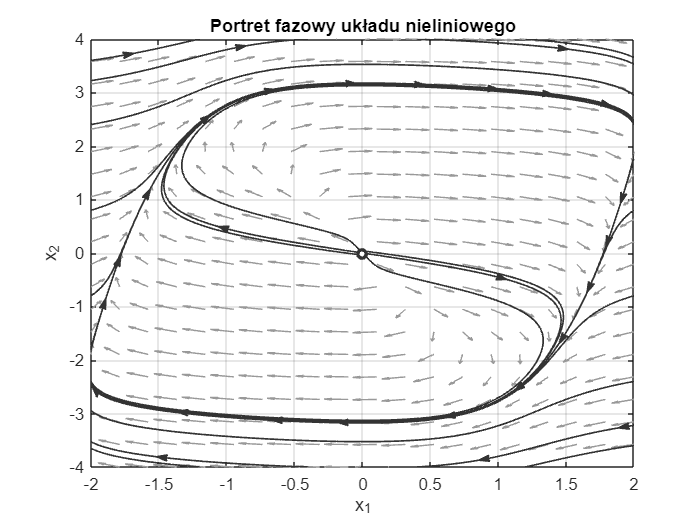

plotpp(@(t,x)[-x(1)^3 - a*x(1) + x(2); -x(1)], 'xlim', [-2, 2], 'ylim', [-4, 4])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
saveas(gcf,'25.png')


plotpp(@(t,x) J*[x(1);x(2)], 'xlim', [-2, 2], 'ylim', [-4, 4])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego")
saveas(gcf,'26.png')

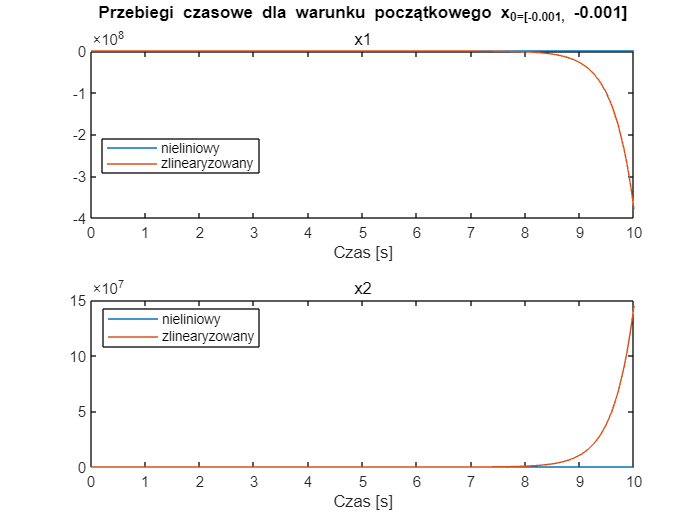


close all;
clear all;
sim_time = 10;
x0=[-0.001 -0.001];
a = -3;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = -3;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t,xx(:,2))
hold on 
plot(t1, xx1(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off


saveas(gcf,'33.png')
close all;
clear all;
sim_time = 10;
x0=[-2 -4];
a = -3;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = -3;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t,xx(:,2))
hold on 
plot(t1, xx1(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off

%saveas(gcf,'34.png')

% a = 1
close all;
a = -3;
x0 = [1 1];
[t,x] = ode45(@(t,x) system33(t,x,a), [0, 100], x0);
J = [-a 1; -1 0];
eig(J)

ans =     2.6180
    0.3820


plotpp(@(t,x)[-x(1)^3 - a*x(1) + x(2); -x(1)], 'xlim', [-2, 2], 'ylim', [-4, 4])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
saveas(gcf,'27.png')


plotpp(@(t,x) J*[x(1);x(2)], 'xlim', [-2, 2], 'ylim', [-4, 4])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego")
saveas(gcf,'28.png')

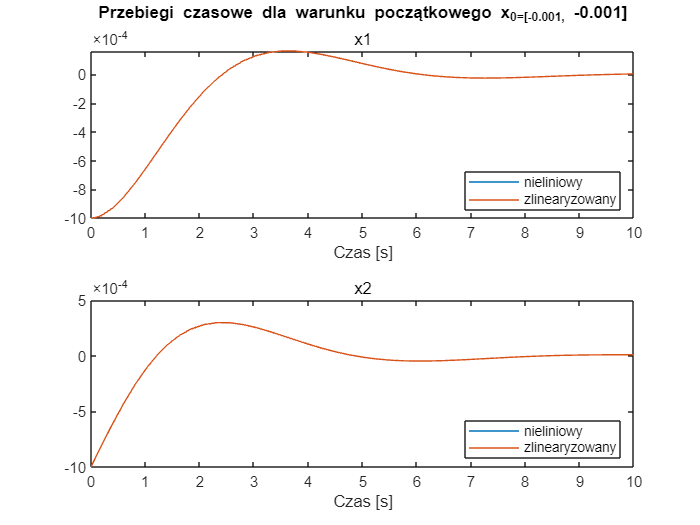

close all;
clear all;
sim_time = 10;
x0=[-0.001 -0.001];
a = 1;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = 1;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t,xx(:,2))
hold on 
plot(t1, xx1(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off
saveas(gcf,'35.png')

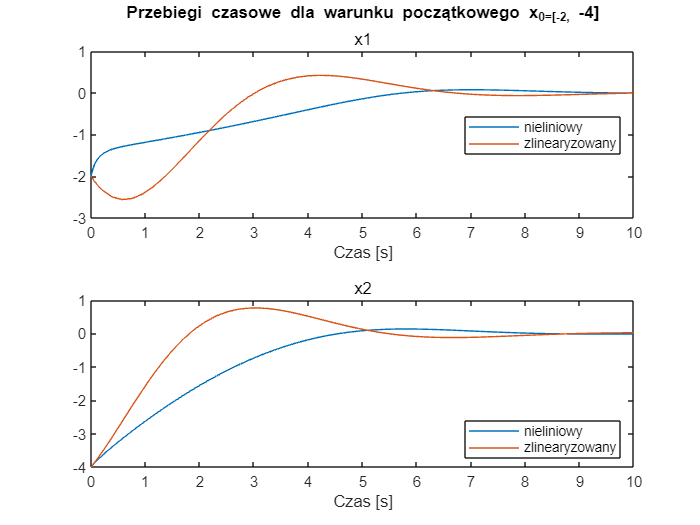

close all;
clear all;
sim_time = 10;
x0=[-2 -4];
a = 1;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = 1;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t,xx(:,2))
hold on 
plot(t1, xx1(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off
saveas(gcf,'36.png')

% a = 3
close all;
a = 3;
x0 = [1 1];
[t,x] = ode45(@(t,x) system33(t,x,a), [0, 100], x0);
J = [-a 1; -1 0];
eig(J)

ans =    -2.6180
   -0.3820


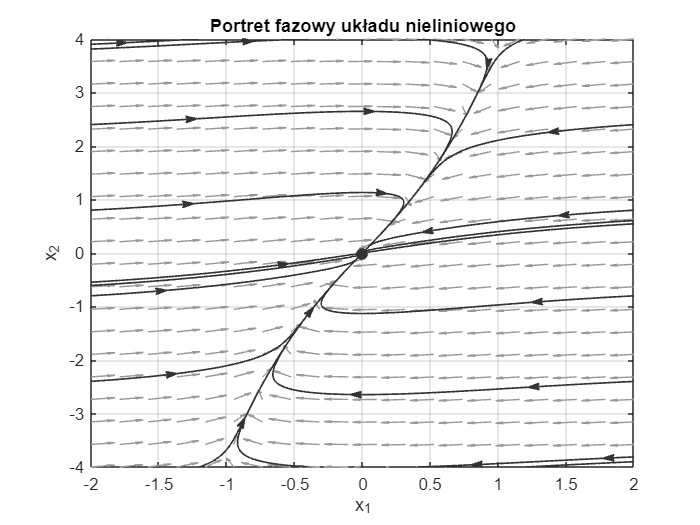

plotpp(@(t,x)[-x(1)^3 - a*x(1) + x(2); -x(1)], 'xlim', [-2, 2], 'ylim', [-4, 4])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu nieliniowego")
saveas(gcf,'29.png')

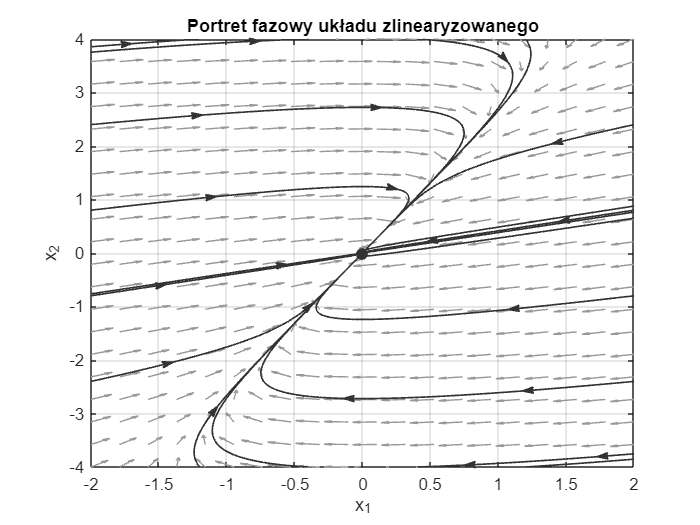

plotpp(@(t,x) J*[x(1);x(2)], 'xlim', [-2, 2], 'ylim', [-4, 4])
xlabel("x_1")
ylabel("x_2")
title("Portret fazowy układu zlinearyzowanego")
saveas(gcf,'30.png')

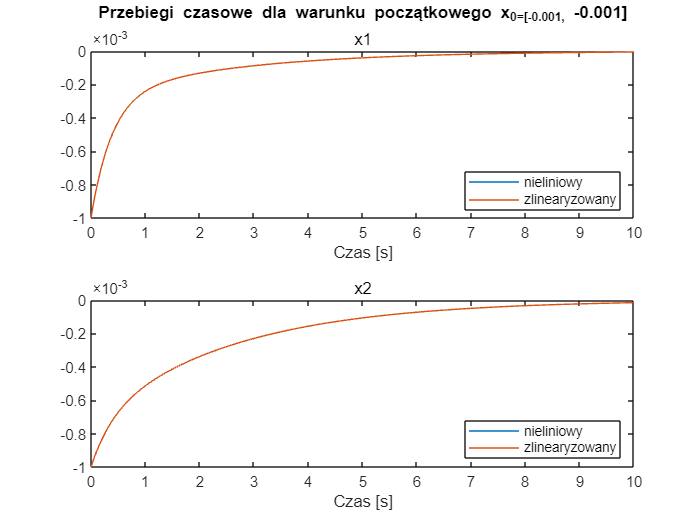

close all;
clear all;
sim_time = 10;
x0=[-0.001 -0.001];
a = 3;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = 3;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t,xx(:,2))
hold on 
plot(t1, xx1(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off
saveas(gcf,'37.png')

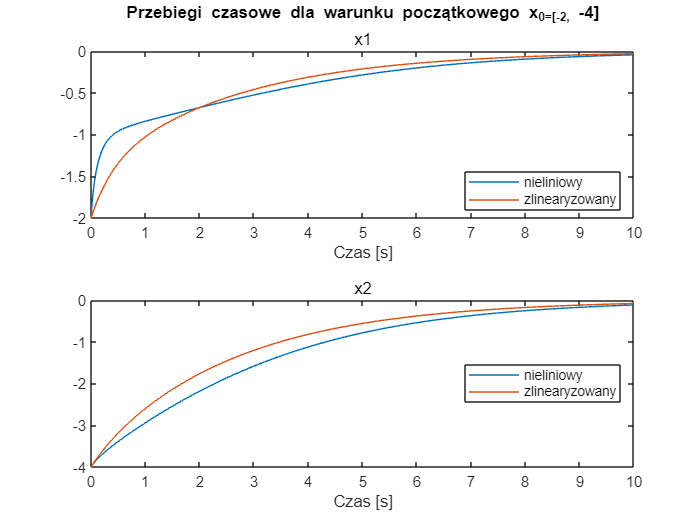

close all;
clear all;
sim_time = 10;
x0=[-2 -4];
a = 3;
%x=[0,0];
% x=[-sqrt(-c/d), 0];
% x=[sqrt(-c/d), 0];
A=[-a, 1; -1, 0];
[t, xx] = ode45(@(t,x) system33(t,x,a), [0 sim_time], x0);
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
figure 
subplot(2,1,1)
a = 3;
plot(t,xx(:,1))
hold on
plot(t1, xx1(:,1))
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('x1')
xlabel("Czas [s]")
hold off
legend("nieliniowy","zlinearyzowany","Location","best")

subplot(2,1,2)
plot(t,xx(:,2))
hold on 
plot(t1, xx1(:,2))
subtitle('x2')
xlabel("Czas [s]")
legend("nieliniowy","zlinearyzowany","Location","best")
hold off
saveas(gcf,'38.png')

A=[-a, 1; -1, 0];
aa = [-3 -1 1 3];
for i = 1: length(aa)
    eig(get_matrix(aa(i)))
end

ans =     2.6180
    0.3820


ans =    0.5000 + 0.8660i
   0.5000 - 0.8660i


ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


ans =    -2.6180
   -0.3820


function matrix = get_matrix(a)
    matrix = [-a, 1; -1, 0];
end

function dxdt = system31(t,x,b,c,d)
    dxdt = zeros(2,1);
    dxdt(1) = x(2);
    dxdt(2) = -c*x(1) - d*x(1)^3 - b*x(2);
end

function dxdt = system32(t,x,c,l,m, g)
    dxdt = zeros(2,1);
    dxdt(1) = x(2);
    dxdt(2) = -(g/l) *sin(x(1)) - (c/(l*m))*x(2);
end

function dxdt = system33(t,x,a)
    dxdt = zeros(2,1);
    dxdt(1) = -x(1)^3 - a*x(1) + x(2);
    dxdt(2) = -x(1);
end

function dxdt = kolos(t,x,a)
    dxdt = zeros(2,1);
    dxdt(1) = -120*x(1) - 4*x(1)^2 - 2*x(1)*x(2);
    dxdt(2) = 60*x(2)-2*x(2)^2 - x(1)*x(2);
end

